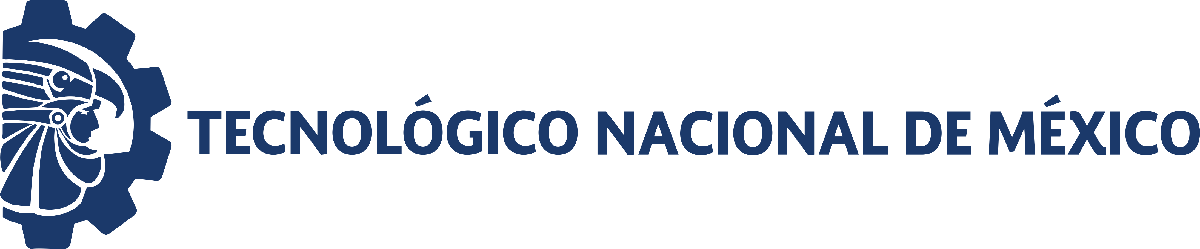

# **Modelling *****Saccharomyces cerevisiae***** for the production of fermented beverages**

Paul A. Valle, Yolocuauhtli Salazar, Luis N. Coria, Nicolas O. Soto-Cruz, Jesus B. Paez-Lerma

Postgraduate Program in Engineering Sciences, BioMath Research Group, Tecnologico Nacional de Mexico/IT Tijuana, Blvd. Alberto Limon Padilla s/n, Tijuana 22454, Mexico

Postgraduate Program in Engineering, Tecnologico Nacional de Mexico/IT Durango, Blvd. Felipe Pescador 1830 Ote., Durango 34080, Mexico

Departament Chemical and Biochemical Engineering, Tecnologico Nacional de Mexico/IT Durango, Blvd. Felipe Pescador 1830 Ote., Durango 34080, Mexico

## Abstract

Mezcal is a traditional distilled spirit beverage from the state of Durango, Mexico, which is obtained by the fermentation of Agave duranguensis sugars. In this work, we formulate a mechanistic model consisting of three first-order Ordinary Differential Equations (ODEs) to describe ethanol production for mezcal by the *Saccharomyces cerevisiae* yeast using glucose and fructose as substrates. These equations were fitted to three different sets of experimental data, representing the concentrations of glucose [x(t)], fructose [y(t)], and ethanol [z(t)] in g/L per hour. A nonlinear regression algorithm was designed in MATLAB to fit the model to each set of experimental data where values of parameters were estimated with a 95% confidence interval. The goodness of fit of the model was evaluated both quantitatively and qualitatively by means of the coefficient of determination (R-squared), the Akaike Information Criterion (AIC), and numerical simulations that illustrate data approximation and prediction in the short-term. Furthermore, conditions for the existence of a localizing domain in the nonnegative octant as well as sufficient conditions for asymptotic stability of the unique biologically feasible equilibrium point of the system were derived by means of the Localization of Compact Invariant Sets method and Lyapunov's Stability theory for nonlinear autonomous systems.

**Keywords:** Alcoholic fermentation; Asymptotic stability; Biostatistcs; In silico experimentation; Mechanistic modelling; Ordinary Differential Equations; *Saccharomyces cerevisiae.*

## Experimental data [Initial biomass: 1x10^8 cells/mL]

clc; clear; close all; warning('off','all')
sys = readmatrix("data.csv");
to = sys(:,1);
x1 = sys(:,5); x2 = sys(:,6); x3 = sys(:,7);
y1 = sys(:,8); y2 = sys(:,9); y3 = sys(:,10);
z1 = sys(:,2); z2 = sys(:,3); z3 = sys(:,4);
plotdataraw(to,[x1,x2,x3],[y1,y2,y3],[z1,z2,z3])

xo = smoothdata(mean([x1,x2,x3],2),'gaussian',3);
yo = smoothdata(mean([y1,y2,y3],2),'gaussian',3);
zo = smoothdata(mean([z1,z2,z3],2),'gaussian',3);
T = array2table([to,xo,yo,zo],'VariableNames',{'t [h]','x(t): Glucose [g/L]',...
    'y(t): Fructose [G/L]','z(t): Ethanol [g/L]'}); disp(T); plotdata(to,xo,yo,zo)

## Nonlinear regression, biostatistics and *in silico* experimentation

Consumption of glucose and fructose by *S. cerevisiae* for ethanol production is modeled by means of the following three nonlinear first-order ODEs:


$$$\dot x = - \rho_4xz - \rho_1x$$$



$$$\dot y = - \rho_5yz - \rho_2y$$$



$$$\dot z = \rho_6(x +y)z - \rho_3z$$$


rho0 = [0.001;0.001;0.001];
rho1 = log(2)/840960; rho2 = log(2)/1680; rho3 = 1.1*max([rho1;rho2]);
[mdl,xa,ya,za] = variant(to,xo,yo,zo,rho0,[rho1,rho2,rho3]); plotfit([to,to],[xo,xa],[yo,ya],[zo,za])

## Approximation and prediction

rho456 = table2array(mdl.Coefficients(:,1)); rho = [rho1;rho2;rho3;rho456];
tend = 2*max(to);
[t,x,y,z] = system(xo(1),yo(1),zo(1),rho,tend);
plotprediction(to,xo,yo,zo,t,x,y,z);

## Functions

### Function: Nonlinear regression algorithm

function [mdl,xa,ya,za] = variant(to,xo,yo,zo,rho0,rho)
    x0 = xo(1); p1 = rho(1);
    y0 = yo(1); p2 = rho(2);
    z0 = zo(1); p3 = rho(3);
    to = [to;to;to];
    fo = [xo;yo;zo];

    function fi = model(p,t)
        p4 = p(1); p5 = p(2); p6 = p(3);
        dt = 1E-3;
        t = reshape(t,[],3); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;
        z = zeros(n+1,1); z(1) = z0;
    
        for i = 1:n
            [fx,fy,fz] = f(x(i),y(i),z(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            
            [fxn,fyn,fzn] = f(xn,yn,zn);         
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
        end
        
        function [dx,dy,dz] = f(x,y,z)
            dx = - p4*x*z - p1*x;
            dy = - p5*y*z - p2*y;
            dz = + p6*(x + y)*z - p3*z;
        end

        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        zi = zeros(length(t),1);
        for j = 1:length(t)
            k = abs(time-t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
            zi(j) = z(k);
        end
        fi = [xi;yi;zi];
    end

    mdl = fitnlm(to,fo,@model,rho0);
    
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pValue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['rho4';'rho5';'rho6'];
    fprintf(['\nSample size (n): ',num2str(numel(fo))])
    fprintf(['\nParameters to be estimated (pars): ',num2str(numel(rho0))])
    fprintf(['\nDegrees of freedom: ',num2str(dof)])
    fprintf(['\nalpha: ',num2str(alpha)])
    fprintf(['\nt-Student value: ',num2str(tval)])
    fprintf(['\nAdjusted R-squared: ',num2str(mdl.Rsquared.Adjusted)])
    fprintf(['\nCorrected AIC (n/pars < 40): ',num2str(mdl.ModelCriterion.AICc),'\n']) 
    % https://www.mathworks.com/help/econ/information-criteria.html
    fprintf('\nFixed parameter values')
    fprintf(['\nrho1: ',num2str(p1)])
    fprintf(['\nrho2: ',num2str(p2)])
    fprintf(['\nrho3: ',num2str(p3),'\n\n'])
    Results = table(Parameters,Estimate,SE,MoE,CI95,pValue);
    disp(Results)
    fa = reshape(mdl.Fitted,[],3);
    xa = fa(:,1); ya = fa(:,2); za = fa(:,3);
    Rx = stats(xo,xa); Ry = stats(yo,ya); Rz = stats(zo,za); R2 = [Rx;Ry;Rz];
    vars = ['x(t)';'y(t)';'z(t)'];
    fprintf('\nR-squared results for each variable\n\n')
    Rsquared = table(vars,R2); disp(Rsquared)
end

### Function: Mathematical model for prediction

function [ti,xi,yi,zi] = system(x0,y0,z0,p,tend)
    p1 = p(1); p2 = p(2); p3 = p(3);
    p4 = p(4); p5 = p(5); p6 = p(6);
    dt = 1E-3;
    t = (0:dt:tend)';
    n = round(max(t)/dt);
    x = zeros(n+1,1); x(1) = x0;
    y = zeros(n+1,1); y(1) = y0;
    z = zeros(n+1,1); z(1) = z0;

    for i = 1:n
        [fx,fy,fz] = f(x(i),y(i),z(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        zn = z(i) + fz*dt;
        [fxn,fyn,fzn] = f(xn,yn,zn);         
        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
        z(i+1) = z(i) + (fz + fzn)*dt/2;
    end
    
    function [dx,dy,dz] = f(x,y,z)
        dx = - p4*x*z - p1*x;
        dy = - p5*y*z - p2*y;
        dz = + p6*(x + y)*z - p3*z;
    end

    ti = t(1:1/(dt*10):end);
    xi = x(1:1/(dt*10):end);
    yi = y(1:1/(dt*10):end);
    zi = z(1:1/(dt*10):end);
end

### Function: R-squared

function [R2,RMSE,prom,Sigma2,Sigma] = stats(xo,xa)
    prom = mean(xo);
    n = length(xo);
    RSS = 0; TSS = 0;
    
    for i = 1:n
        RSS = RSS + (xo(i)-xa(i))^2;
        TSS = TSS + (xo(i)-prom)^2;
    end
    
    R2 = 1 - RSS/TSS;
    RMSE =  sqrt(RSS/n);
    Sigma2 = TSS/n;
    Sigma = sqrt(Sigma2);
end

### Plots

function plotdataraw(t,x,y,z)
    set(figure(),'Color','w')
    FS = 12; BEERcolors = [0.12,0.41,0.55;0.25,0.51,0.47;0.91,0.66,0.07];
    set(gcf,'Units','Centimeters','Position',[2,2,25,10])
    
    subplot(1,3,1)
    hold on; grid off; colororder(BEERcolors)
    plot(t,x(:,1),'-o','LineWidth',1,'MarkerSize',4)
    plot(t,x(:,2),'-o','LineWidth',1,'MarkerSize',4)
    plot(t,x(:,3),'-o','LineWidth',1,'MarkerSize',4)
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t)$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 72]); xticks(0:8:72)
    ylim([-1 15]); yticks(-1:1:15)
    L = legend('$x_1(t)$','$x_2(t)$','$x_3(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','NorthEast')
    title(L,'Glucose')
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(1,3,2)
    hold on; grid off; colororder(BEERcolors)
    plot(t,y(:,1),'-o','LineWidth',1,'MarkerSize',4)
    plot(t,y(:,2),'-o','LineWidth',1,'MarkerSize',4)
    plot(t,y(:,3),'-o','LineWidth',1,'MarkerSize',4)
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 72]); xticks(0:8:72)
    ylim([0 110]); yticks(0:10:110)
    L = legend('$y_1(t)$','$y_2(t)$','$y_3(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','NorthEast')
    title(L,'Fructose')
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(1,3,3)
    hold on; grid off; colororder(BEERcolors)
    plot(t,z(:,1),'-o','LineWidth',1,'MarkerSize',4)
    plot(t,z(:,2),'-o','LineWidth',1,'MarkerSize',4)
    plot(t,z(:,3),'-o','LineWidth',1,'MarkerSize',4)
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$z(t)$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 72]); xticks(0:8:72)
    ylim([0 65]); yticks(0:5:65)
    L = legend('$z_1(t)$','$z_2(t)$','$z_3(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','SouthEast')
    title(L,'Ethanol')
    set(gca,'FontName','Times New Roman','FontSize',FS)

    exportgraphics(gcf,'matlab_dataraw.pdf','ContentType','vector')
    exportgraphics(gcf,'matlab_dataraw.png','Resolution',600)
    print('matlab_dataraw','-dsvg'); print('matlab_dataraw','-depsc')
end

function plotdata(t,x,y,z)
    set(figure(),'Color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[2,2,25,10])
    
    subplot(1,3,1)
    hold on; grid off
    plot(t,x,'x','LineWidth',1,'MarkerSize',5,'Color',[0.3,0.5,0.2])
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t)$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 72]); xticks(0:8:72)
    ylim([0 15]); yticks(0:1:15)
    L = legend('$x(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','NorthEast')
    title(L,'Glucose')
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(1,3,2)
    hold on; grid off
    plot(t,y,'x','LineWidth',1,'MarkerSize',5,'Color',[0.5,0.1,0.05])
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 72]); xticks(0:8:72)
    ylim([0 110]); yticks(0:10:110)
    L = legend('$y(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','NorthEast')
    title(L,'Fructose')
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(1,3,3)
    hold on; grid off
    plot(t,z,'x','LineWidth',1,'MarkerSize',5,'Color',[0,0.25,0.4])
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$z(t)$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 72]); xticks(0:8:72)
    ylim([0 65]); yticks(0:5:65)
    L = legend('$z(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','SouthEast')
    title(L,'Ethanol')
    set(gca,'FontName','Times New Roman','FontSize',FS)

    exportgraphics(gcf,'matlab_data.pdf','ContentType','vector')
    exportgraphics(gcf,'matlab_data.png','Resolution',600)
    print('matlab_data','-dsvg'); print('matlab_data','-depsc')
end

function plotfit(t,x,y,z)
    set(figure(),'Color','w')
    FS = 12; tend = max(t,[],'all');
    set(gcf,'Units','Centimeters','Position',[2,2,25,10])
    
    subplot(1,3,1)
    hold on
    plot(t(:,1),x(:,1),'x','LineWidth',1,'MarkerSize',5,'Color',[0.3,0.5,0.2])
    plot(t(:,1),x(:,2),'-','LineWidth',1,'Color',[0.5,0.5,0.5])
    yline(0,'--','LineWidth',1,'Color','k')
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t)$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 tend]); xticks(0:tend/9:tend)
    ylim([-1 15]); yticks(-1:1:15)
    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','NorthEast')
    title(L,'Glucose')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    subplot(1,3,2)
    hold on; grid off
    plot(t(:,1),y(:,1),'x','LineWidth',1,'MarkerSize',5,'Color',[0.5,0.1,0.05])
    plot(t(:,1),y(:,2),'-','LineWidth',1,'Color',[0.5,0.5,0.5])
    yline(0,'--','LineWidth',1,'Color','k')
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 tend]); xticks(0:tend/9:tend)
    ylim([-10 110]); yticks(-10:10:110)
    L = legend('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','NorthEast')
    title(L,'Fructose')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    subplot(1,3,3)
    hold on; grid off
    plot(t(:,1),z(:,1),'x','LineWidth',1,'MarkerSize',5,'Color',[0,0.25,0.4])
    plot(t(:,1),z(:,2),'-','LineWidth',1,'Color',[0.5,0.5,0.5])
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$z(t)$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 tend]); xticks(0:tend/9:tend)
    ylim([0 65]); yticks(0:5:65)
    L = legend('$z_o(t)$','$z_a(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','SouthEast')
    title(L,'Ethanol')
    set(gca,'FontName','Times New Roman','FontSize',FS)

    exportgraphics(gcf,'matlab_results.pdf','ContentType','vector')
    exportgraphics(gcf,'matlab_results.png','Resolution',600)
    print('matlab_results','-dsvg'); print('matlab_results','-depsc')
end

function plotprediction(to,xo,yo,zo,t,x,y,z)
    set(figure(),'Color','w')
    FS = 12; tend = max(t,[],'all');
    set(gcf,'Units','Centimeters','Position',[2,2,25,10])
    
    subplot(1,3,1)
    hold on; grid off
    plot(to,xo,'x','LineWidth',1,'MarkerSize',5,'Color',[0.3,0.5,0.2])
    plot(t,x,'-','LineWidth',1,'Color',[0.5,0.5,0.5])
    yline(0,'--','LineWidth',1,'Color','k')
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t)$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 tend]); xticks(0:tend/9:tend)
    ylim([-1 15]); yticks(-1:1:15)
    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','NorthEast','Box','on')
    title(L,'Glucose')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    subplot(1,3,2)
    hold on; grid off
    plot(to,yo,'x','LineWidth',1,'MarkerSize',5,'Color',[0.5,0.1,0.05])
    plot(t,y,'-','LineWidth',1,'Color',[0.5,0.5,0.5])
    yline(0,'--','LineWidth',1,'Color','k')
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 tend]); xticks(0:tend/9:tend)
    ylim([-10 110]); yticks(-10:10:110)
    L = legend('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','NorthEast','Box','on')
    title(L,'Fructose')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    subplot(1,3,3)
    hold on; grid off
    plot(to,zo,'x','LineWidth',1,'MarkerSize',5,'Color',[0,0.25,0.4])
    plot(t,z,'-','LineWidth',1,'Color',[0.5,0.5,0.5])
    xlabel('$t$ $[h]$','Interpreter','Latex','FontSize',FS)
    ylabel('$z(t)$ $[g/L]$','Interpreter','Latex','FontSize',FS)
    xlim([0 tend]); xticks(0:tend/9:tend)
    ylim([0 65]); yticks(0:5:65)
    L = legend('$z_o(t)$','$z_a(t)$');
    set(L,'Interpreter','Latex','FontSize',FS-1,'Location','SouthEast','Box','on')
    title(L,'Ethanol')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    exportgraphics(gcf,'matlab_prediction.pdf','ContentType','vector')
    exportgraphics(gcf,'matlab_prediction.png','Resolution',600)
    print('matlab_prediction','-dsvg'); print('matlab_prediction','-depsc')
end